## Preprocessing the cello data

Notes: There seems to be a large DC component masking the impulse response of the cello modes, apply different filtering approaches to uncover the modes.

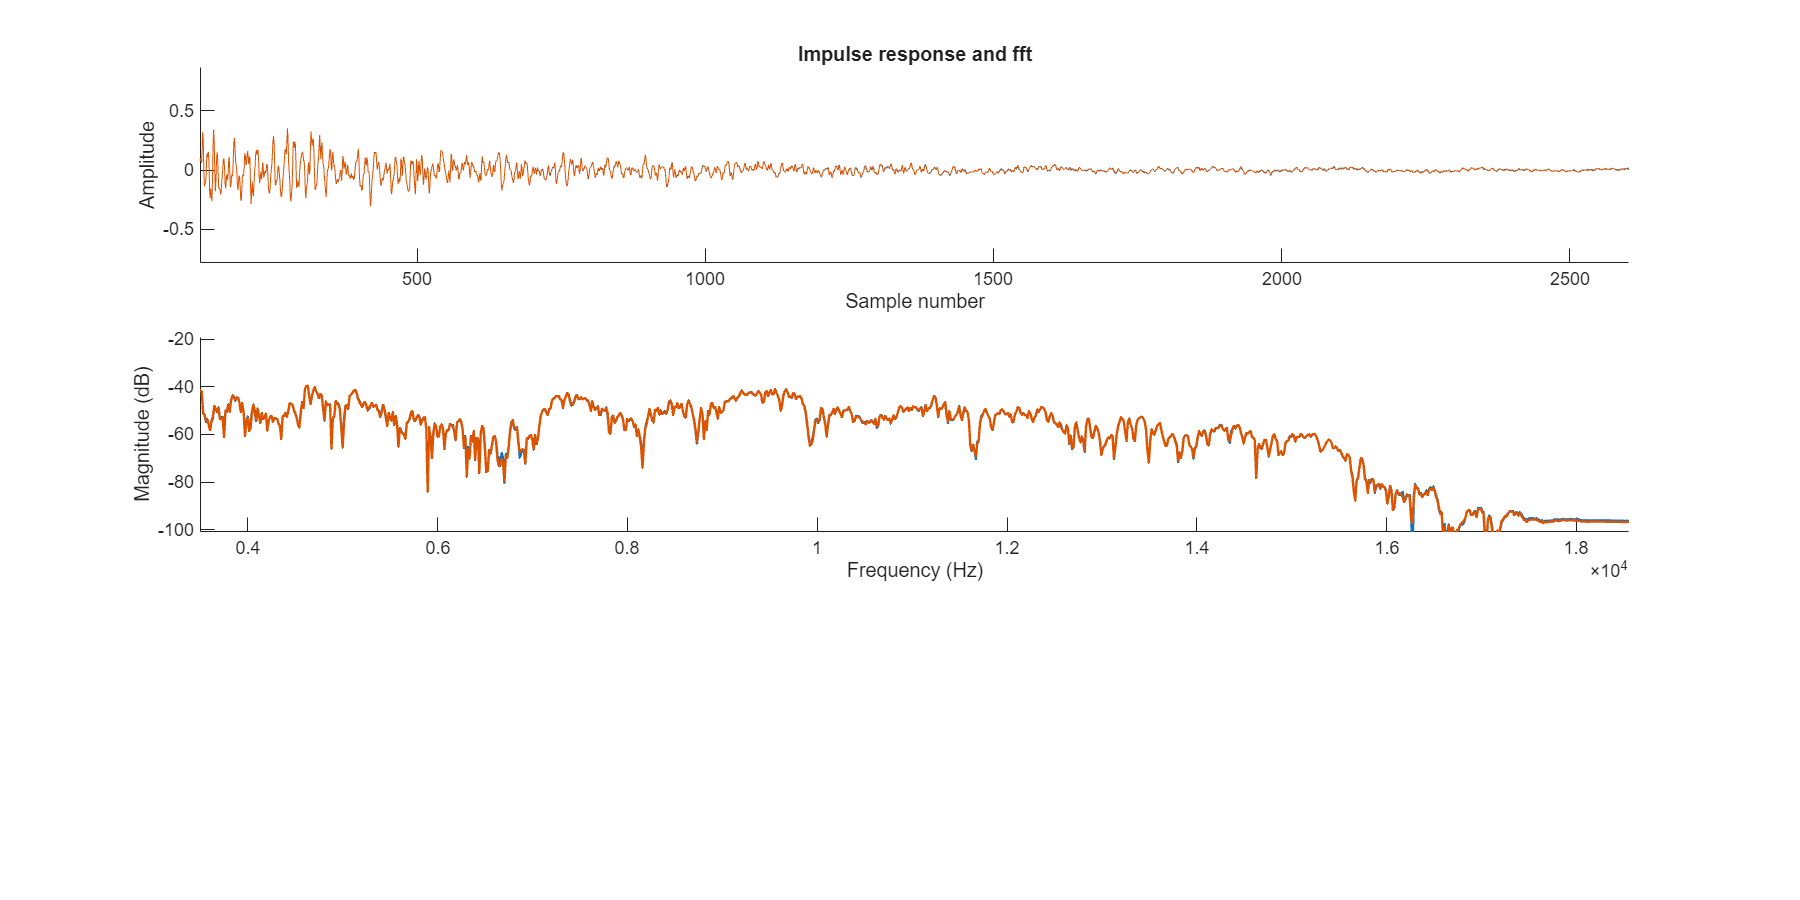

% Import the data.
celloData = importdata("cello1.wav");
admittance = importdata("IWK_cello_admittance.txt");
test = importdata("IWK_cello_test_impulse_response.txt");

% Cutoff sample.
dataCutoff = 3000;

% Truncation. Need to decide a good way to threshold this.
celloTf = celloData.data(1 : dataCutoff);
tfFs = celloData.fs;

% Try removing the mean to see if this fixes the DC component.
celloTf = celloTf - mean(celloTf); % No dice.

[celloFft, freqAx] = singleSidedFft(celloTf, tfFs);

opts = eraConfig();
opts.returnDebug = true;
    svdTolerance = 749;

[outputSignal, frequencies, dampingFactors, amplitudes, ...
    phases, modes, debug] = eigensystemRealisation(celloTf, ...
    svdTolerance, tfFs, opts);

eraFft = singleSidedFft(outputSignal, tfFs);

fig = figure;
fig.Position = [0 0 1200 600];
t = tiledlayout(3, 1);

nexttile
hold on
plot(celloTf)
plot(outputSignal)
ylabel("Amplitude")
xlabel("Sample number")
title("Impulse response and fft")

nexttile
hold on
plot(freqAx, 20*log10(abs(celloFft)), 'LineWidth', 1.2)
plot(freqAx, 20*log10(abs(eraFft)), 'LineWidth', 1.2)
ylim([-120 0])
xlim([0 max(freqAx)])
ylabel('Magnitude (dB)')
xlabel('Frequency (Hz)')


timeVector = admittance(:, 1)';
impulse = admittance(:, 2)';